%% C´odigo 1
% Gerar uma matriz com 3 linhas e 10000 colunas de n´umeros aleat´orios
% entre 0.0 e 1.0 (ou seja, cada coluna representa uma experiˆencia):
experiencias = rand(15,10000);
% Gerar uma matriz com 3 linhas e 10000 colunas com o valor 1 se o valor
% da matriz anterior for superior a 0.5 (ou seja, se saiu cara) ou com o
% valor 0 caso contr´ario (ou seja, saiu coroa):
lancamentos = experiencias > 0.5; % 0.5 corresponde a 1 - prob. de caras
% Gerar um vetor linha com 10000 elementos com a soma dos valores de cada
% coluna da matriz anterior (ou seja, o n´umero de caras de cada experiˆencia):
resultados= sum(lancamentos);   % por omissão, soma as colunas
% Gerar um vetor linha com 10000 elementos com o valor 1 quando o valor do
% vetor anterior ´e 2 (ou seja, se a experiˆencia deu 2 caras) ou 0 quando ´e
% diferente de 2:
sucessos= resultados==6;
% Determinar o resultado final dividindo o n´umero de experiˆencias com 2
% caras pelo n´umero total de experiˆencias:
probSimulacao= sum(sucessos)/10000

probSimulacao = 0.1514

% ex4
function y = probCaras(prob,nLanc,nCaras,Nexp)

    lancamentos = rand(nLanc,Nexp) > prob;
    sucessos = sum(lancamentos) == nCaras;
    y = sum(sucessos)/Nexp;

end
%N= 1e5; %número de experiˆencias
%p = 0.5; %probabilidade de cara
%k = 6; %número de caras
%n = 20; %número de lanc¸amentos

%stem([0:5],rand(1,6))
%stem([0:20],probCaras(0.5,20,6,1e5))    %% not 

p = 0.5;
k = 6;
n = 20;

prob = nchoosek(n,k)*p^k*(1-p)^(n-k)

prob = 0.0370

% probabilidade analitica torneiras defeituosas
% a)
p = 0.3;
n = 5;
k = 3;

prob = nchoosek(n,k)*p^k*(1-p)^(n-k)

prob = 0.1323

% probabilidade experiencial torneiras defeituosas
% a)
N = 1e5;
p = 0.3;
k = 3;
n = 5;
madeInChina = rand(n,N) < p;
Defeituosas = sum(madeInChina) == k;

prob = sum(Defeituosas)/N

prob = 0.1320

% b) analiticamente
p = 0.3;
n = 5;
k1 = 0;
k2 = 1;
k3 = 2;

prob = nchoosek(n,k1)*p^k1*(1-p)^(n-k1) + nchoosek(n,k2)*p^k2*(1-p)^(n-k2) + nchoosek(n,k3)*p^k3*(1-p)^(n-k3)

prob = 0.8369

% b) experiencial
N = 1e5;
p = 0.3;
k = 2;
n = 5;
madeInChina = rand(n,N) < p;
Defeituosas = sum(madeInChina) <= k;

prob = sum(Defeituosas)/N

prob = 0.8372

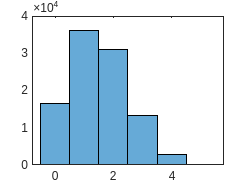

% 6. c)

N = 1e5;
p = 0.3;
k = 2;
n = 5;
madeInChina = rand(n,N) < p;
Defeituosas = sum(madeInChina);

%histogram(Defeituosas,'Normalization','probability')
histogram(Defeituosas)

% TPC
% R1:
n = 10

n = 10

factorial(n)

ans = 3628800